# MyS01_C:

**Limpieza del entorno de trabajo**

clear     % limpieza del espacio de trabajo
clc       % limpieza de línea de comando
close all % cerrar todas las figuras

### Configuración usuario 

Se muestran los ajustes elejidos por el usuario aplicables a cualquier modelo de simulación discreta. 

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 10;
solver.step = 1;

### a. Modelaje del sistema propuesto


$$x_{n+1} =\alpha_1 \cdot x_n -\beta_2 \cdot y_n \;\;$$



$$y_{n+1} =\alpha_2 \cdot y_n -\beta_1 \cdot x_n \;$$


Donde:

- $x=\;$número de unidades del bando azul.

- $\alpha_1 =\;$capacidad defensiva del bando azul.

- $\beta_1 =\;$capacidad ofensiva del bando azul.

- $y=\;$número de unidades del bando rojo.

- $\alpha_2 =\;$capacidad defensiva del bando rojo.

- $\beta_2 =\;$capacidad ofensiva del bando rojo.

Además tenemos que en defensa, el bando azul es mejor, pero en ataque el bando rojo es más rápido.


$$\begin{array}{l}
\alpha_{1\;} >\alpha_2 \\
\beta_{1\;} <\beta_2 
\end{array}$$


### b. Estudio analítico de la estabilidad

Para calcular la estabilidad del sistema, calculamos el jacobiano de las ecuaciones.

syms x_n y_n alpha_1 alpha_2 beta_1 beta_2
J = jacobian([(alpha_1)*x_n - beta_2*y_n, alpha_2*y_n - beta_1*x_n], [x_n, y_n])

$$J = \left(\begin{array}{cc} \alpha_{1} & -\beta_{2}\\ -\beta_{1} & \alpha_{2} \end{array}\right)$$

Y sus autovalores que vienen dados por los valores de la matriz diagonal del jacobiano (J).

[~, D] = eig(J);

lambda1 = D(1,1)

$$lambda1 = \frac{\alpha_{1}}{2}+\frac{\alpha_{2}}{2}-\frac{\sqrt{{\alpha_{1}}^{2}-2\,\alpha_{1}\,\alpha_{2}+{\alpha_{2}}^{2}+4\,\beta_{1}\,\beta_{2}}}{2}$$

lambda2 = D(2,2)

$$lambda2 = \frac{\alpha_{1}}{2}+\frac{\alpha_{2}}{2}+\frac{\sqrt{{\alpha_{1}}^{2}-2\,\alpha_{1}\,\alpha_{2}+{\alpha_{2}}^{2}+4\,\beta_{1}\,\beta_{2}}}{2}$$

Para que el sistema fuese estable, ambos autovalores (lamda1 y lamda2) han de ser menor que 1.

### c. Capacidades ofensivas y defensivas

Que no haya vencedores ni vencidos quiere decir que el sistema se estabilice (que haya un empate entre el número de unidades de ambos bandos).

Como hemos calculado antes los requesitos para la estabilidad del sistema, tenemos que obtener los factores de capacidades defensivas y ofensivas ($\alpha ,\beta$ respectivamente) que verifiquen lamda1 y lambda2 < 1. 

alpha_1 = [0.55 0.65 2];
alpha_2 = [0.4 0.5 1.5];
beta_1 = [0.3 0.4 1];
beta_2 = [0.2 0.3 0.5];

Teniendo en cuenta $\begin{array}{l}
\alpha_{1\;} >\alpha_2 \\
\beta_{1\;} <\beta_2 
\end{array}$ ; probamos posibles valores que pueden tomar, y comparamos en la gráfica el comportamiento de los sistemas para cada valor.

#### Ejecución simulación

Constantes del modelo

F0 = [8, 10]; % unidades iniciales de cada bando

Nombre del modelo

model_name = "combate";

sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output.

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout;            % Dataset container of signals
num_signals = numElements(signals); % Number of signals

#### Representación gráfica

Se dibuja cada señal

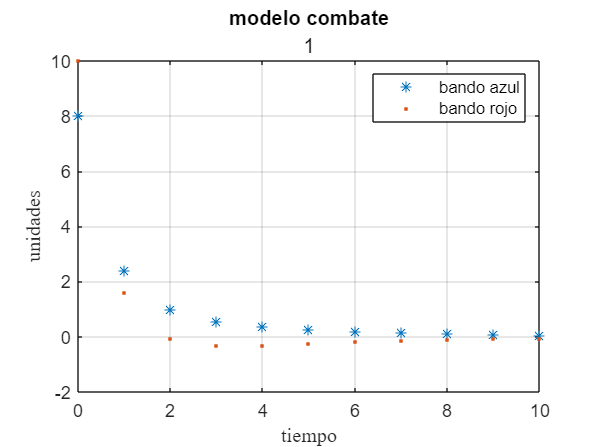

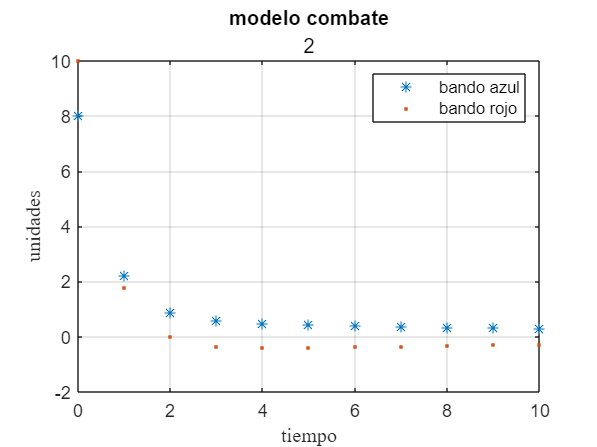

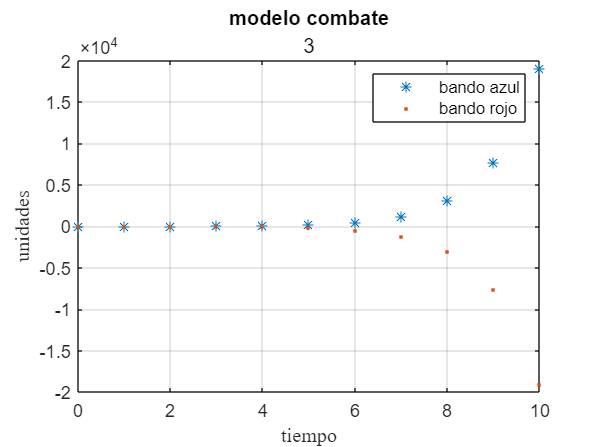

signal1_values = signals{1}.Values.Data;
signal2_values = signals{2}.Values.Data;
signal_time = signals{1}.Values.Time;

[m, n] = size(signal1_values);
for i =1:n
    figure
    plot(signal_time, signal1_values(:,i),"*")
    hold on
    plot(signal_time, signal2_values(:,i),".")
    grid on
    xlabel("tiempo","FontName","latex");
    ylabel("unidades","FontName","latex");
    title("modelo combate",i);
    legend('bando azul','bando rojo');
    hold off
end 

Según las gráficas obtenidas, las unidades de cada bando se estabilizan siendo ambas 0 en los 2 primeros casos (cuando dimos los valores). Por lo que no hay ganador del combate en esos escenarios. Mientras que en la tercera gráfica, los puntos divergen y acaba ganando el bando azul. 

### d. Desaparición de uno de los bandos

Si los enfrentamientos terminaran cuando alguno de los dos bandos desapareciera,

¿cuánto duraría dicho enfrentamiento? ¿Quién resultaría vencedor?

n = size(signal1_values);
for i=1:n
    if signal1_values(i) <= 0 
        fprintf('El vencedor es el bando azul y la duración del combate fue %d',signal_time(i))
        signal_time(i)
        break
    end
    if signal2_values(i) <= 0 
        fprintf('El vencedor es el bando azul y la duración del combate fue %d',signal_time(i))
        break
    end
end

El vencedor es el bando azul y la duración del combate fue 2

% también se podría poner un STOP al modelo con condicion if <= 0 STOP

Que concuerda con los resultados de la gráfica, donde el bando rojo pierde todas sus unidades antes que el azul.

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

**Decorador de la función sim de MATLAB**

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

Se utiliza el bloque Out1 para cada señal.